# Assignment 1

## Question 1

Calculate pdf

X: alpha=1.7, beta=-0.4, scale=2, mu=0.3

% pdf of simulation 
data_1=stabgen(1000000,1.7,-0.4,2,0.3,1);
int1=(max(data_1)-min(data_1))/1000000;
[pdf1_1,x1_1]=ksdensity(data_1,(min(data_1):int1:max(data_1)),'Function','pdf');

% pdf of true density 
x1_2= -8:.04:8;
pdf1_2=asymstab(x1_2,1.7,-0.4,2,0.3);

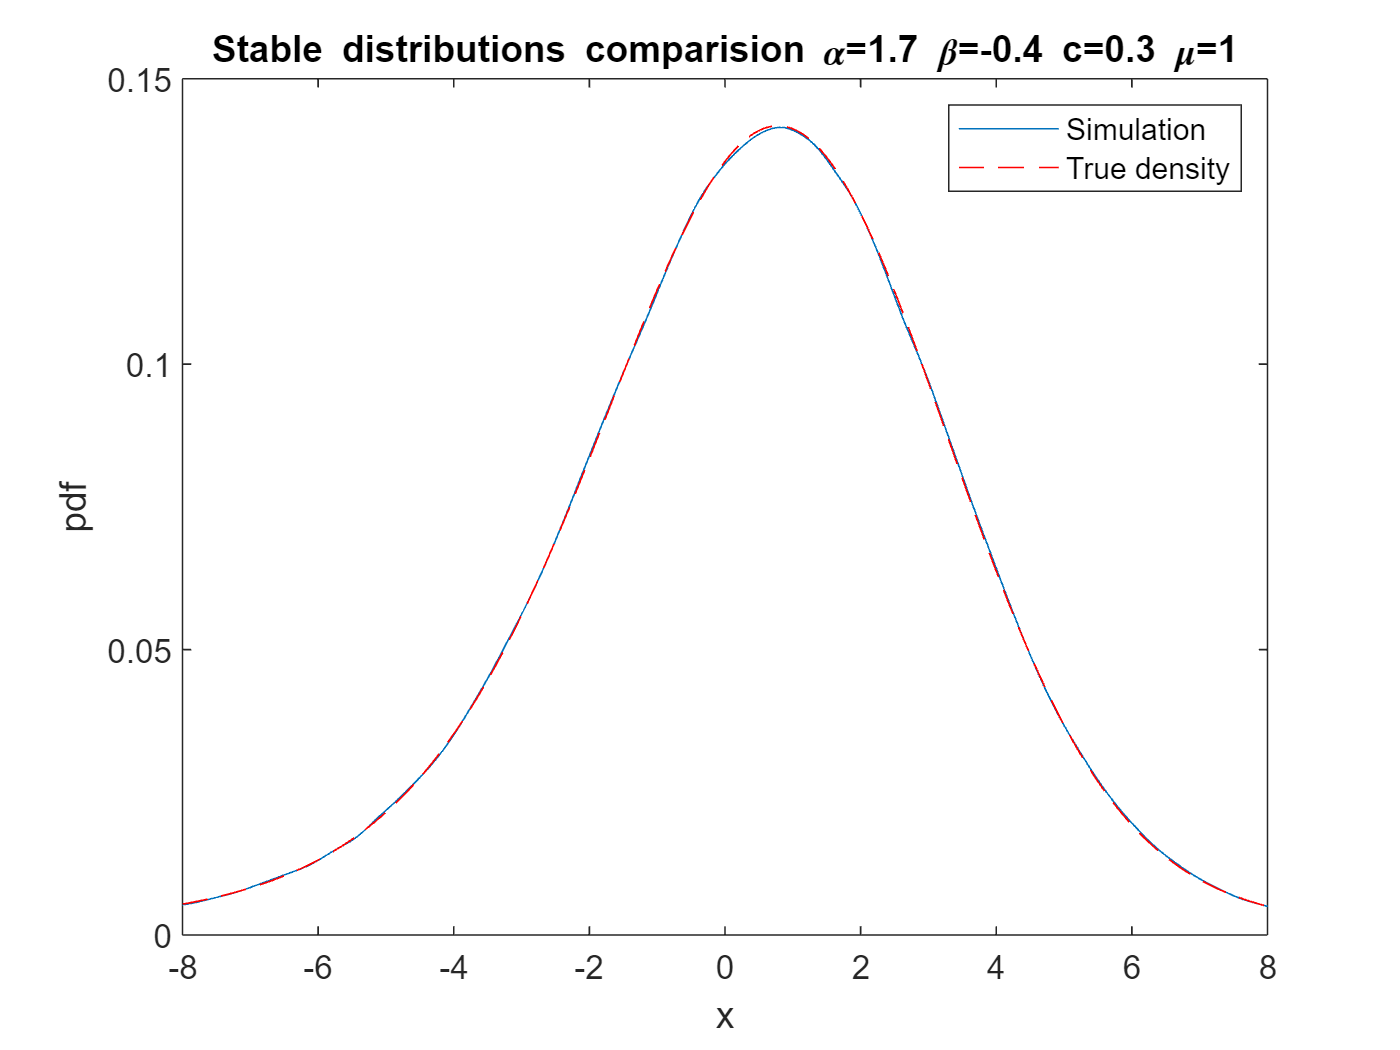

figure
plot(x1_1,pdf1_1)
hold on;
plot(x1_2,pdf1_2, 'r--')
xlim([-8 8]);
title('Stable distributions comparision \alpha=1.7 \beta=-0.4 c=0.3 \mu=1')
legend('Simulation','True density')
xlabel('x') 
ylabel('pdf') 
hold off;

## Question 2

Calculate sum of 

X1: alpha1=1.7, beta1=-0.4, scale1=2, mu1=-0.5

X2: alpha2=1.7, beta2=-0.5, scale2=1, mu2=0.3

% pdf of simulation
data_2=sum_stabgen(1000000,1.7,-0.4,2,-0.5,1.7,-0.5,1,0.3,1,2);
int2=(max(data_2)-min(data_2))/1000000;
[pdf2_1,x2_1]=ksdensity(data_2,(min(data_2):int2:max(data_2)),'Function','pdf');

% pdf of true density
x2_2 = -8:.04:8;
pdf2_2 = sum_asymstab(x2_2,1.7,-0.4,2,-0.5,1.7,-0.5,1,0.3);

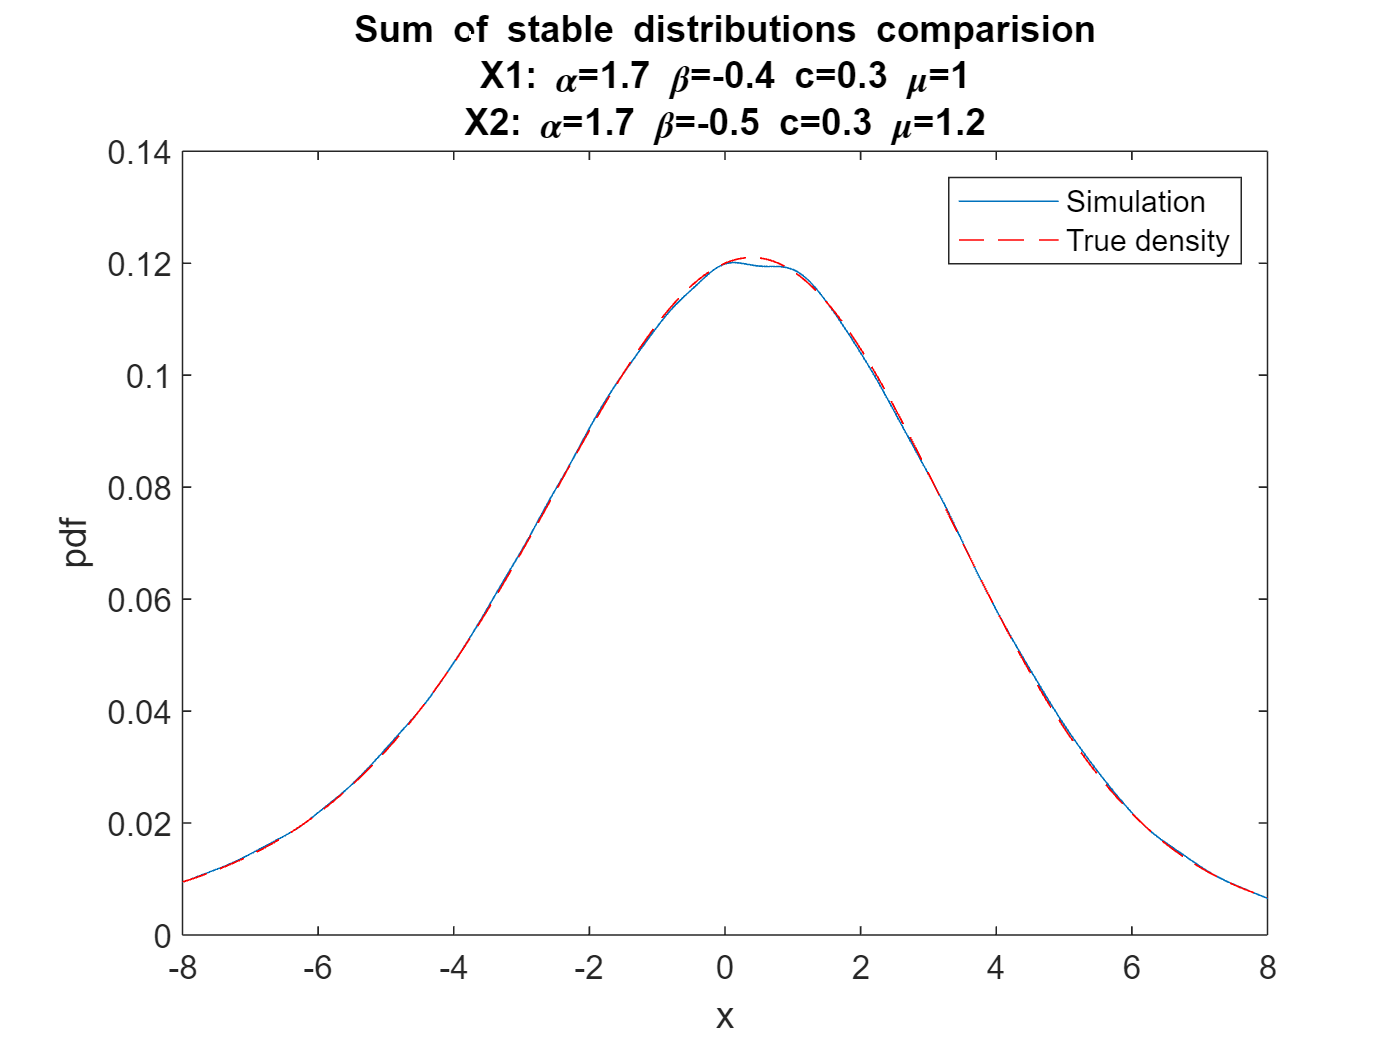

figure
plot(x2_1,pdf2_2);
hold on;
plot(x2_2,pdf2_1,'r--');
xlim([-8 8]);
title("Sum of stable distributions comparision"+newline+"X1: \alpha=1.7 \beta=-0.4 c=0.3 \mu=1"+newline+ "X2: \alpha=1.7 \beta=-0.5 c=0.3 \mu=1.2")
legend('True density','Simulation')
xlabel('x') 
ylabel('pdf') 
hold off;

## Question 3a

Calculate sum of 

X1: alpha1 = 1.6, beta1=0, scale1=1, mu1=0

X2: alpha2 = 1.8, beta2=0, scale2=1, mu2=0

% sum pdf true density using convolution


% sum pdf true density using inversion formula
x3a_2 = -8:.04:8;
pdf3a_2 = sum_asymstab(x3a_2,1.6,0,1,0,1.8,0,1,0);

% sum pdf of simulation
data_3a=sum_stabgen(1000000,1.6,0,1,0,1.8,0,1,0,1,2);
int3a=(max(data_3a)-min(data_3a))/1000000;
[pdf3a_3,x3a_3]=ksdensity(data_3a,(min(data_3a):int3a:max(data_3a)),'Function','pdf');

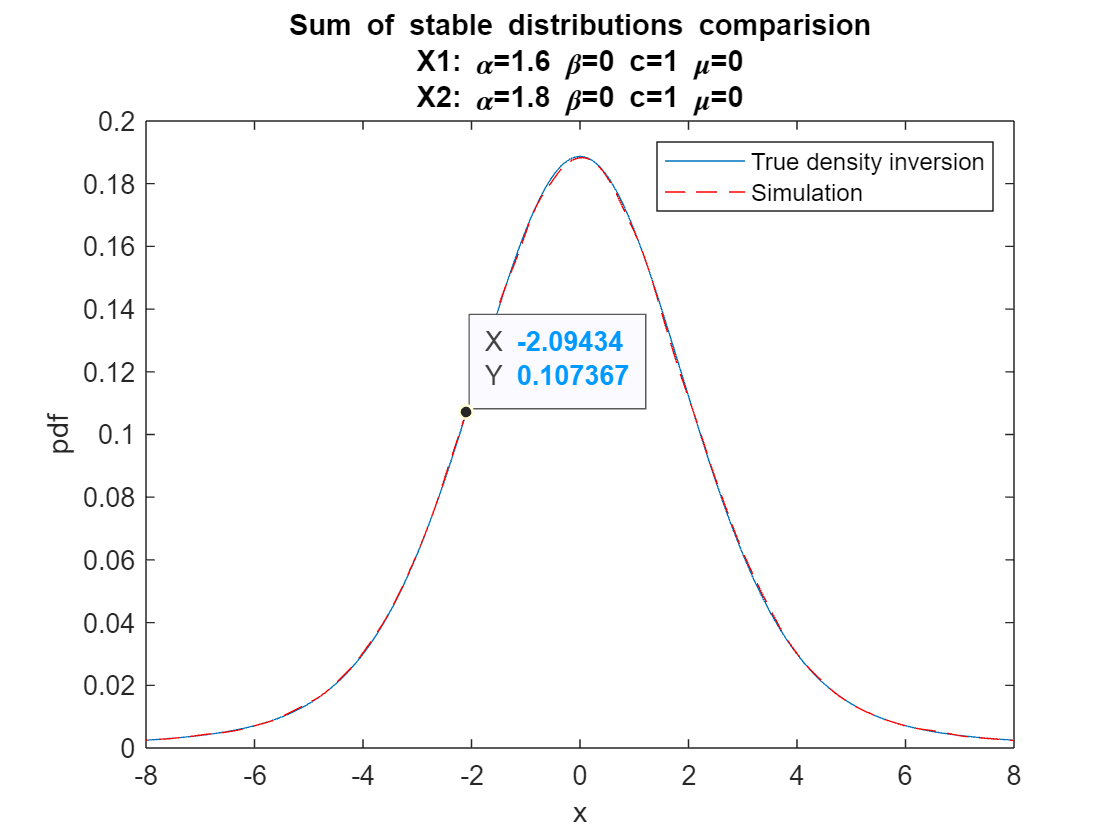

figure
plot(x3a_2,pdf3a_2);
hold on;
plot(x3a_3,pdf3a_3,'r--');
xlim([-8 8]);
title("Sum of stable distributions comparision"+newline+"X1: \alpha=1.6 \beta=0 c=1 \mu=0"+newline+ "X2: \alpha=1.8 \beta=0 c=1 \mu=0")
legend('True density inversion','Simulation')
xlabel('x') 
ylabel('pdf') 
hold off;

## Question 3b

Calculate sum of 

X1: alpha1 = 1.5, beta1=0, scale1=1, mu1=0

X2: alpha2 = 1.9, beta2=0, scale2=1, mu2=0

% sum pdf true density using convolution


% sum pdf true density using inversion formula
x3b_2 = -8:.04:8;
pdf3b_2 = sum_asymstab(x3b_2,1.5,0,1,0,1.9,0,1,0);

% sum pdf of simulation
data_3b=sum_stabgen(1000000,1.5,0,1,0,1.9,0,1,0,1,2);
int3b=(max(data_3b)-min(data_3b))/1000000;
[pdf3b_3,x3b_3]=ksdensity(data_3b,(min(data_3b):int3b:max(data_3b)),'Function','pdf');

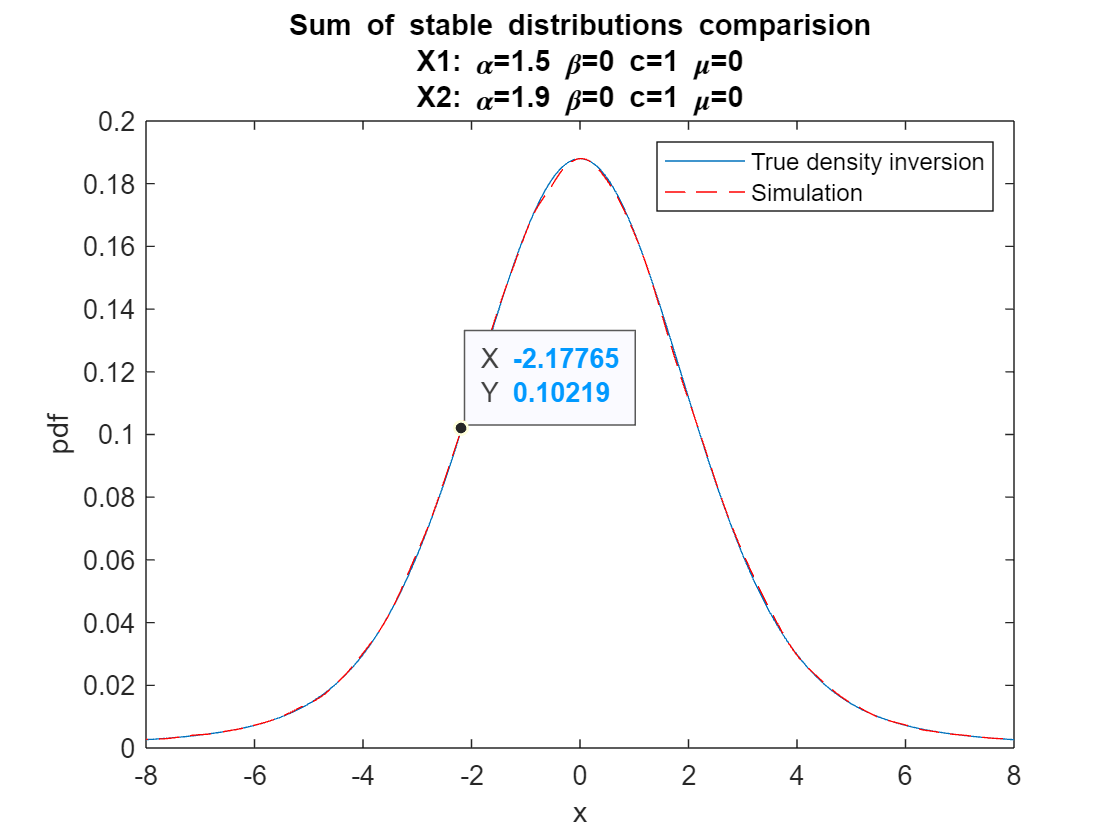

figure
plot(x3b_2,pdf3b_2);
hold on;
plot(x3b_3,pdf3b_3,'r--');
xlim([-8 8]);
title("Sum of stable distributions comparision"+newline+"X1: \alpha=1.5 \beta=0 c=1 \mu=0"+newline+ "X2: \alpha=1.9 \beta=0 c=1 \mu=0")
legend('True density inversion','Simulation')
xlabel('x') 
ylabel('pdf') 
hold off;

## Question 4 

Calculate ES for xi = 0.01

alpha= 1.7, beta = 0, scale = 1, location = 0 

[ES_theory, VaR1] = asymstabES(0.01,1.7,0,1,0);

mu_4=0;scale_4=1;
N=1000000; 
X_4 = stabgen(N,1.7,0,1,0,1); 
X_4 = mu_4+scale_4*X_4;
use=X_4(X_4<VaR1);
ES_empirical = mean(use);
disp("Theoretical ES is: "+ES_theory+newline+"Empirical ES is: "+ES_empirical)

Theoretical ES is: -11.4709
Empirical ES is: -11.5489


## Question 5